# Transfer Function

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

Phasor-transformed circuits discussed for a fixed frequency for sources.   The impedance of the capacitor, $1/j\omega C$, and the impedance of the inductor, $j\omega L$, are dependent of frequency . It is interesting to see how the circuits respond to sinusoids as the frequency $\omega$ is scanned from zero to infinity. This can be achieved by transforming the circuit components to impedances, $1/j\omega C$ and $j\omega L$, without defining values of $\omega$, and designating the input and output of the circuit as a function of $\omega$. Then, one finds the ratio of the output to input. The input signal can be voltage or current, and the output signal can be voltage or current. This ratio is called the transfer function$H(\omega)$. By plotting the magnitude of the transfer function $|H(\omega )|$, called the magnitude response, and the phase of the transfer function$\angle H(\omega)$, called the phase response, we can gain more insight into the behavior of the circuit as the frequency is varied. The magnitude is called the gain.

## Learning Objectives

- Be able to find the transfer function of a circuit

- Be able to plot and analyze transfer function  magnitude and phase responses 

#### Example 1. RC Circuit

Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit given in the figure and plot the magnitude and phase responses

                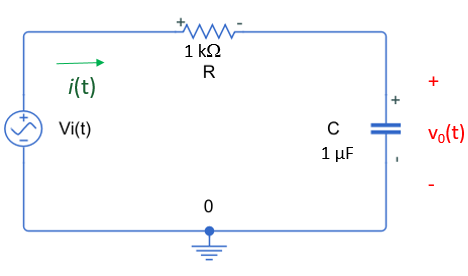

**Solution: **Transfer the circuit into $\omega $ domain 

            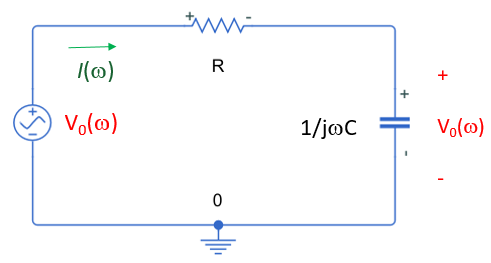

Applying of the voltage divider rule to find $V_0(\omega)$

        
$$V_0(\omega)=\frac{ \frac{1}{j \omega C}}{R+\frac{1}{j \omega C}} V_i (\omega) = \frac{1}{RCj\omega+1}  V_i (\omega) =\frac{ \frac{1}{RC}}{j\omega+\frac{1}{ RC}} V_i (\omega) $$


The transfer function $H(\omega)$can be obtained as 

          
$$H(\omega) = \frac{V_0(\omega)}{ V_i (\omega) } = \frac{ \frac{1}{RC}}{j\omega+\frac{1}{ RC}} $$


syms H(w)
R = 1e3;
C = 1e-6;

H(w)=1/(R*C)/(j*w+1/(R*C))

$$H(w) = \frac{1000}{1000+w\,\mathrm{i}}$$

The magnitude response is given by

            
$$|H(\omega) |=\frac{ \frac{1}{RC}}{ \sqrt { \omega^2+\frac{1}{(RC)^2}}} $$
 

and the phase response is given by

              
$$\angle {H(\omega)} = -tan^{-1} \Big( \frac{\omega }{\frac{1}{ RC}} \Big ) = -tan^{-1}(\omega RC)$$


The magnitude response  can be calculated in decibal [dB]  using  logarithmic form.

            
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

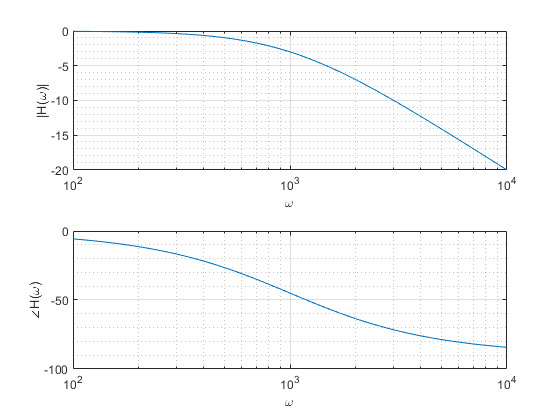

subplot (2,1,1)
w = logspace(2,4);    % 
H=(1/(R*C))./(j*w+1/(R*C));
% semilogx(w, abs(H))
semilogx(w, 20*log10(abs(H)))
grid on; grid minor;
xlabel('\omega'); ylabel('|H(\omega)|');

subplot (2,1,2)
semilogx(w, angle(H)*180/pi)
grid on; grid minor;
xlabel('\omega'); ylabel('\angle{H(\omega)}');

  The gain dropped by 3.01 dB at $\omega_c=\frac{1}{RC}$ or  $|H(\omega_c)|=\frac{H_{max}}{\sqrt 2}=0.707H_{max}$.  This frequency is represent  the 3-dB cutoff frequency and is denoted by $\omega_c$. 

Hmax = max(abs(H));
wc=


Circuit can be simulated  in MATLAB Simulink .[./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

    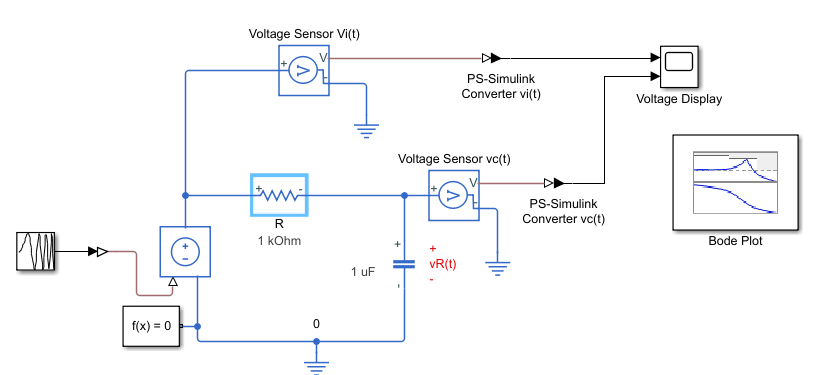

In the simulation, bode plot gives the following figure

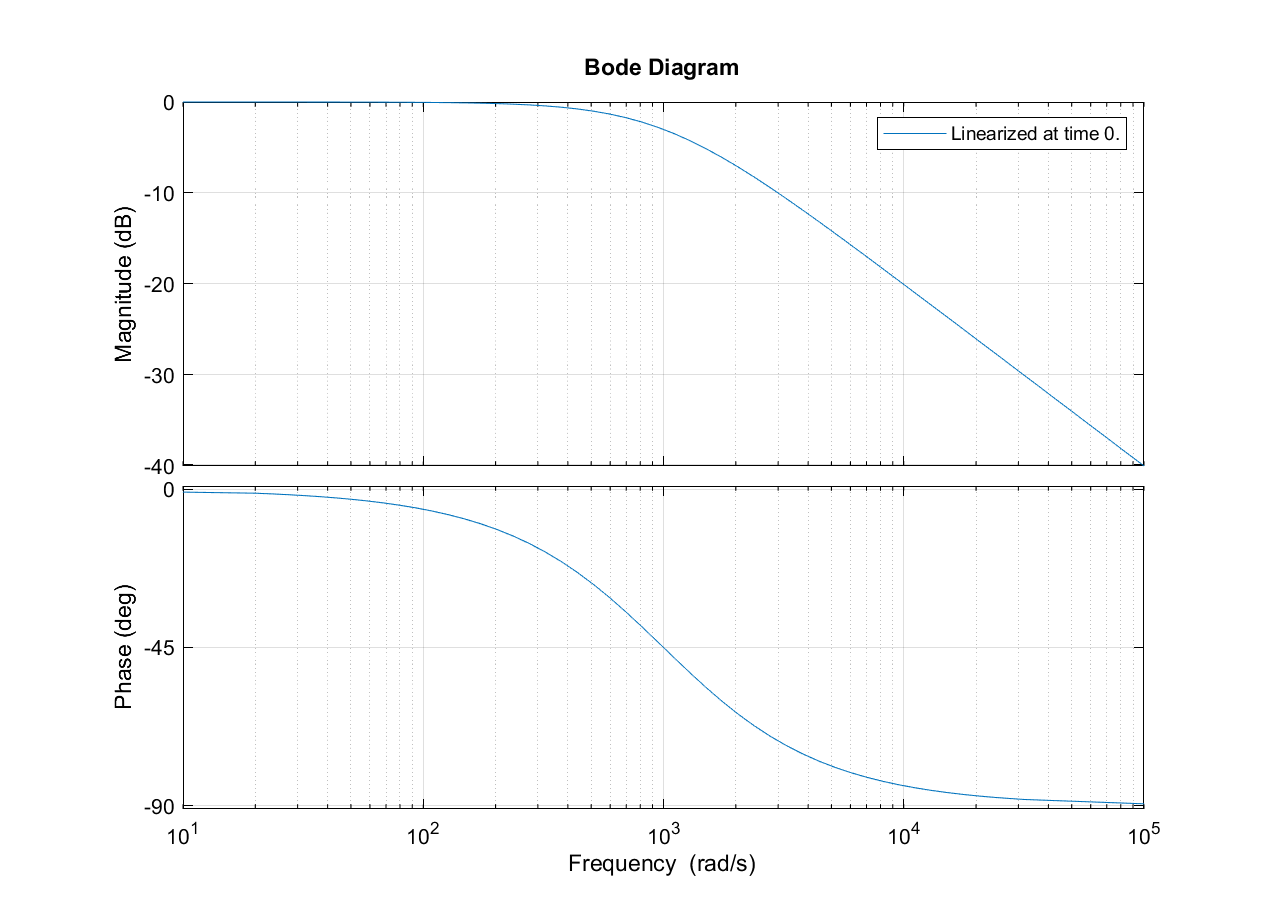

#### Exercise 1. RC Circuit

Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

   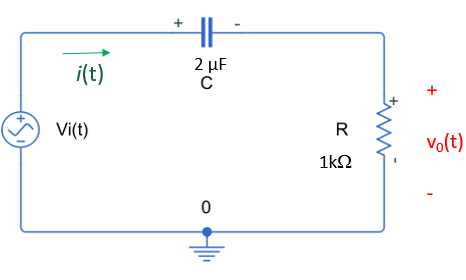

**Solution steps:**

Transfer the circuit into $\omega $ domain 

Apply the voltage divider rule

Find the transfer function $H(\omega)$as

  
$$H(\omega) = \frac{V_0(\omega)}{ V_i (\omega) } $$


% syms H(w)
% R = ?;

$$H(w) = \frac{w\,\mathrm{i}}{10000+w\,\mathrm{i}}$$

% C = ?;
% 
% H(w) = ?


The magnitude response 

and the phase response 

The magnitude response in logarithmic form is given as

            
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

% subplot (2,1,1)
% w = logspace(? ,?);    % 
% H=?;
% % semilogx(w, abs(H))
% semilogx(w, 20*log10(abs(H)))
% grid on; grid minor;
% xlabel('\omega'); ylabel('|H(\omega)|');
% 
% subplot (2,1,2)
% semilogx(w, angle(H)*180/pi)
% grid on; grid minor;
% xlabel('\omega'); ylabel('\angle{H(\omega)}');

Simulate  this exercise using MATLAB Simulink to chek your values

    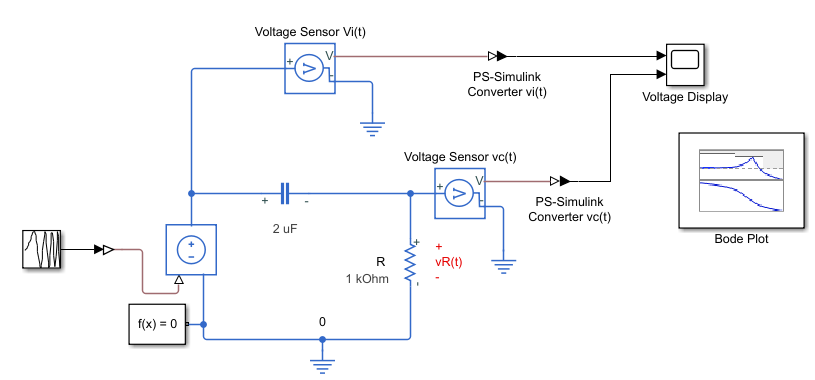

#### Example 2. RL Circuit

Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

               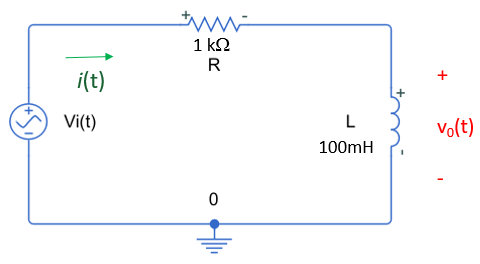

**Solution: **Transfer the circuit into $\omega $ domain 

                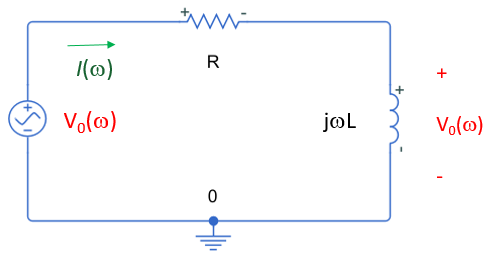

Applying of the voltage divider rule to find $V_0(\omega)$

        
$$V_0(\omega)=\frac{ j \omega L}{R+j \omega L} V_i (\omega) = \frac{ j \omega}{j \omega + \frac{R}{L}} V_i (\omega)$$


The transfer function $H(\omega)$can be obtained as 

          
$$H(\omega) = \frac{V_0(\omega)}{ V_i (\omega) } =  \frac{ j \omega}{j \omega + \frac{R}{L}} $$


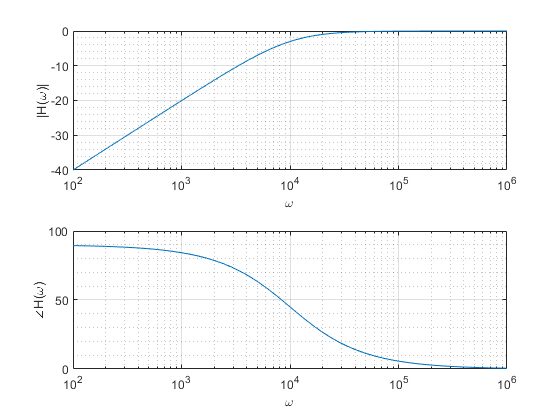

syms H(w)
R = 1e3;
L = 100e-3;

H(w)=(j*w)/(j*w+R/L)


The magnitude response is given by


$$|H(\omega) |=\frac{ \omega}{ \sqrt { \omega^2+ \Big (\frac{R}{L} \Big )^2 }}$$
 

and the phase response is given by

  
$$\angle {H(\omega)} = 90-tan^{-1} \Big( \frac{\omega }{R/L} \Big )= 90 -tan^{-1}(\frac{\omega L}{R})$$


The magnitude response  can be calculated in logarithmic form as


$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

figure()
subplot (2,1,1)
w = logspace(2,6);    % Define w as a vector containing the frequencies from 10 rad/s to 1,000,000 rad/s.
H = j*w./(j*w+R/L);
% semilogx(w, abs(H))
semilogx(w, 20*log10(abs(H)))

$$H(w) = \frac{2500000000}{-w^{2}+50000\,w\,\mathrm{i}+2500000000}$$

grid on; grid minor;
xlabel('\omega'); ylabel('|H(\omega)|');

subplot (2,1,2)
semilogx(w, angle(H)*180/pi)
grid on; grid minor;
xlabel('\omega'); ylabel('\angle{H(\omega)}');

Circuit can be simulated  in MATLAB Simulink 

    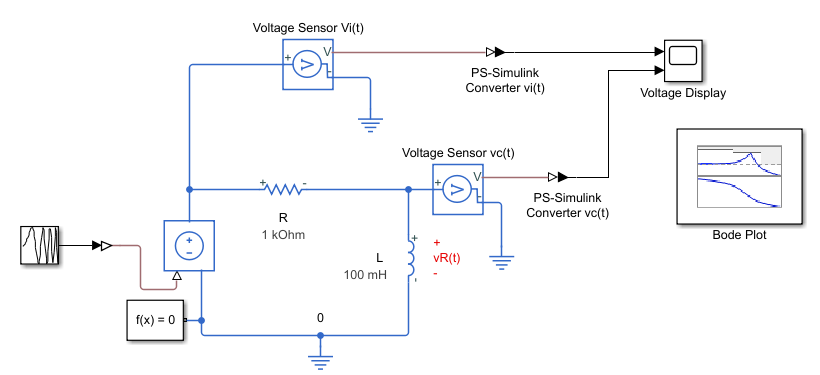

In the simulation, bode plot is shown in the following figure

    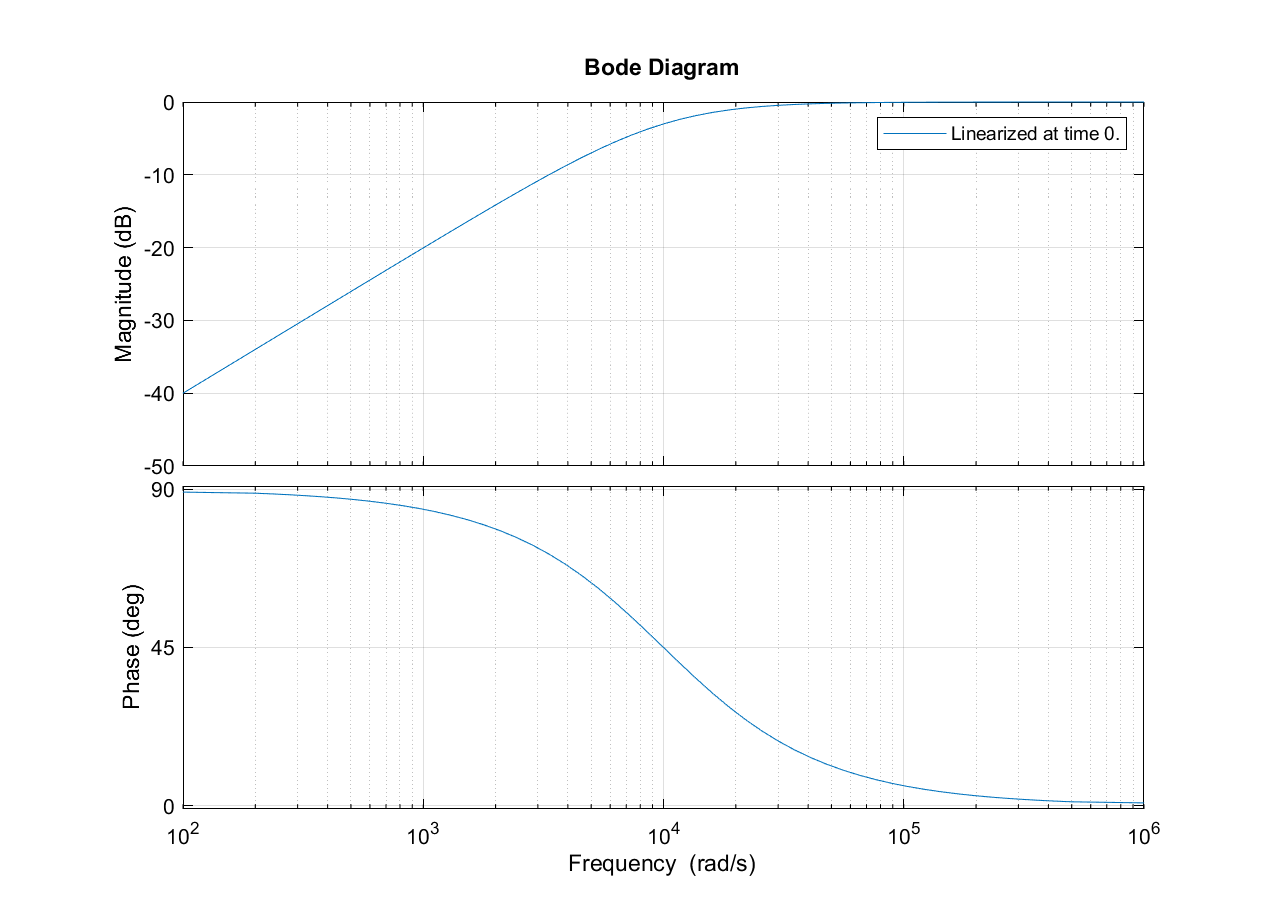

#### Exercise 2. RL Circuit

    Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

           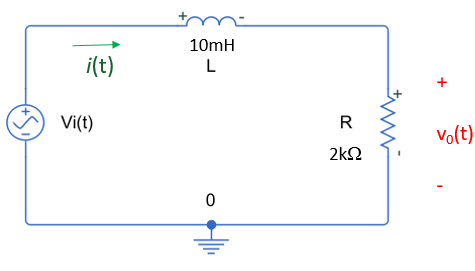

**Solution steps:**

Transfer the circuit into $\omega $ domain 

Apply the voltage divider rule to find $V_0(\omega)$

Find the transfer function $H(\omega)$as

  
$$H(\omega) = \frac{V_0(\omega)}{ V_i (\omega) } $$


% syms H(w)
% R = ?;
% C = ?;
% 
% H(w) = ?


The magnitude response 

and the phase response 

The magnitude response in logarithmic form as

            
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

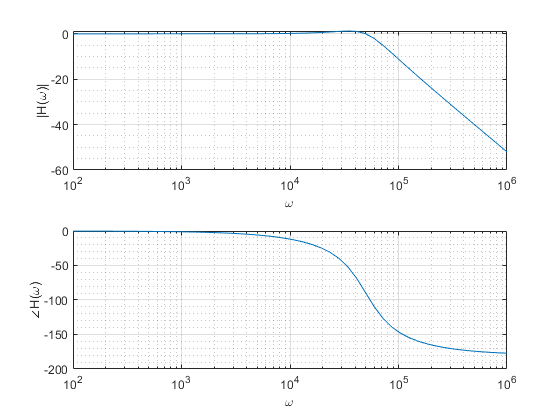

% subplot (2,1,1)
% w = logspace(? ,?);    % 
% H=?;
% % semilogx(w, abs(H))
% semilogx(w, 20*log10(abs(H)))
% grid on; grid minor;
% xlabel('\omega'); ylabel('|H(\omega)|');
% 
% subplot (2,1,2)
% semilogx(w, angle(H)*180/pi)

% grid on; grid minor;
% xlabel('\omega'); ylabel('\angle{H(\omega)}');

Simulate  this exercise using MATLAB Simulink to chek your values

    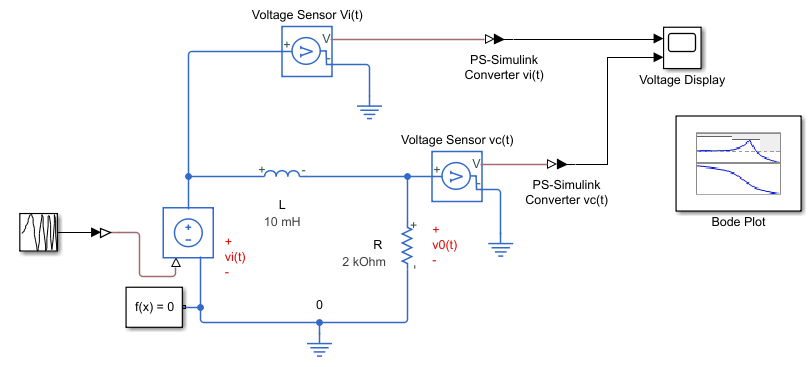

#### Example 3. RLC Circuit

 Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

            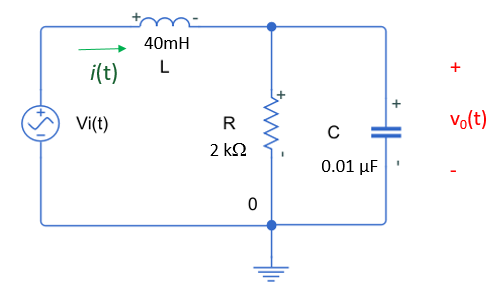

**Solution: **Transfer the circuit into $\omega $ domain 

            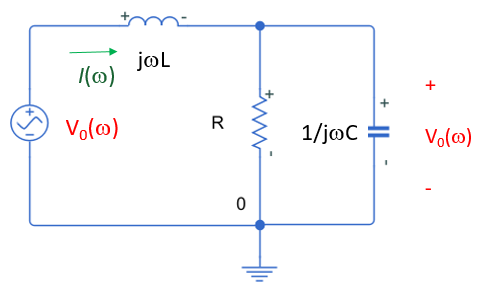

Applying KCl at node to find $V_0(\omega)$

        
$$\frac{V_i(\omega) -V_0i(\omega)}{j\omega L} -  \frac{ V_0 (\omega )}{R} - \frac{ V_0( \omega )}{\frac{1}{j\omega C} }= 0$$


Rearange it 

        
$$\Big ( j \omega C+\frac{1}{R}+  \frac{ 1}{j\omega L} \Big)V_0(\omega) = \frac{1}{j \omega L} V_i (\omega)$$


The transfer function is given

        
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} = \frac{ \frac{1}{j \omega L}} {  j \omega C+\frac{1}{R}+ \frac{ 1}{j\omega L}  $$


        
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} = \frac{ \frac{1}{LC}} {- \omega^2+\frac{1}{RC}j\omega+ \frac{ 1}{LC}  $$


syms H(w)
R = 2e3;
L = 40e-3;
C=0.01e-6;

H(w)=(1/(L*C))/(-w^2+1/(R*C)*j*w+1/(L*C))

$$H(w) = -\frac{50000}{50000+w\,\mathrm{i}}$$

The magnitude response is given by

        
$$|H(\omega)|= \frac{|V_0(\omega)|}{|V_i(\omega)|} = \frac{ \frac{1}{LC}} { \sqrt{ \Big (\frac{ 1}{LC}- \omega^2 \Big )^2+ \Big (\frac{\omega}{RC} \Big )^2 }$$


and the phase response is given by

          
$$\angle {H(\omega)} = -tan^{-1} \Big( \frac{ \frac{\omega }{RC}} { \frac{1}{LC}-\omega ^2} \Big ) $$


The magnitude response  can be calculated in logarithmic form as

        
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude respon and  phase response

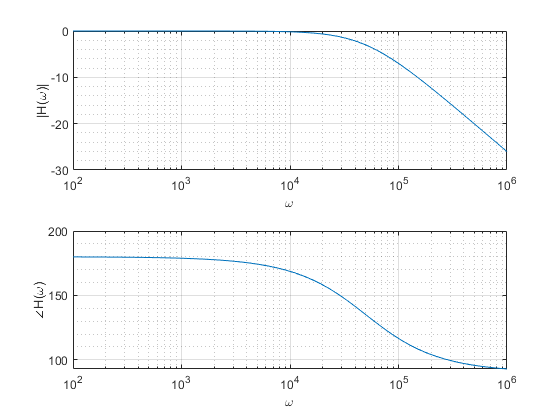

figure()
subplot (2,1,1)
w = logspace(2,6);    % Define w as a vector containing the frequencies from 10 rad/s to 1,000,000 rad/s.

H = (1/(L*C))./(-w.^2+j*w/(R*C)+1/(L*C));
% semilogx(w, abs(H))
semilogx(w, 20*log10(abs(H)))
grid on; grid minor;
xlabel('\omega'); ylabel('|H(\omega)|');

subplot (2,1,2)
semilogx(w, angle(H)*180/pi)
grid on; grid minor;
xlabel('\omega'); ylabel('\angle{H(\omega)}');

Circuit can be simulated  in MATLAB Simulink 

    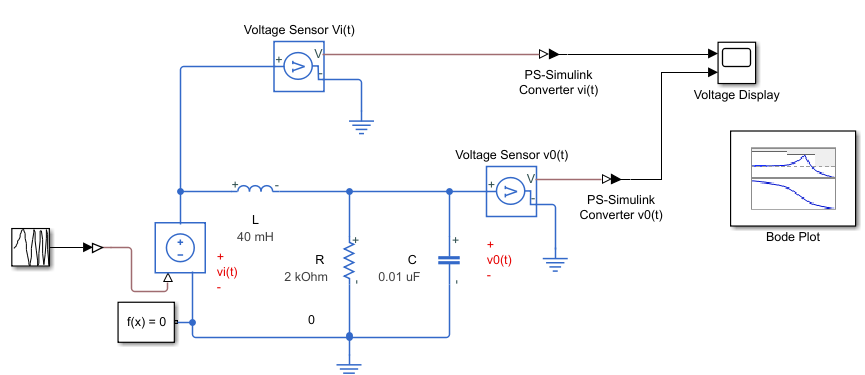

In the simulation, bode plot is shown in the following figure

    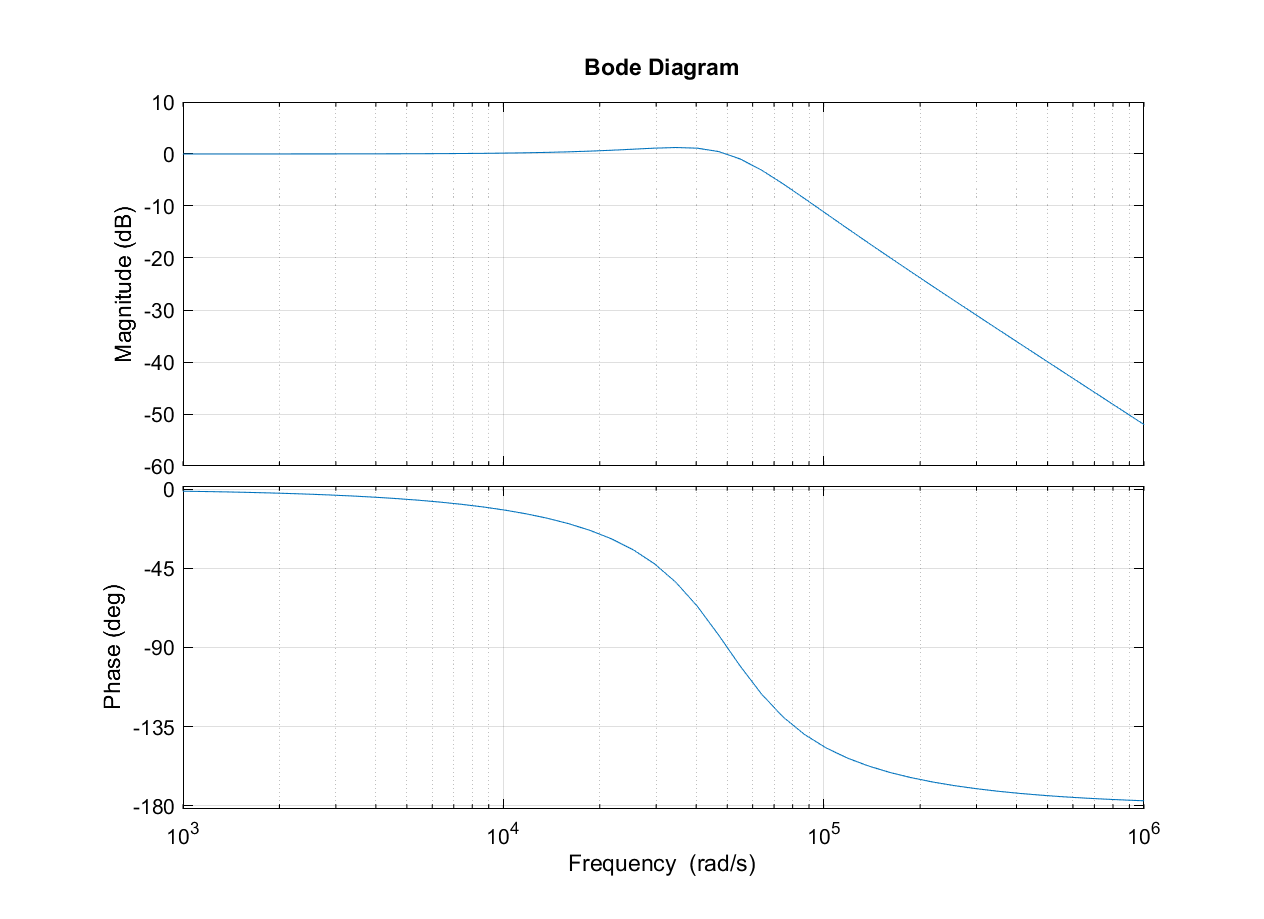

#### Exercise 3. RLC Circuit

 Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

                        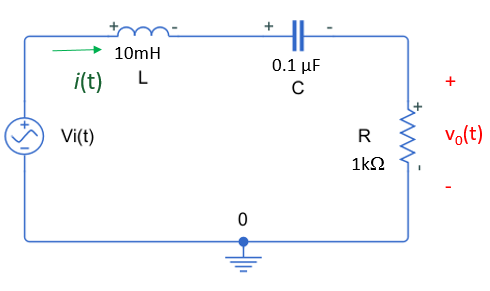

**Solution steps:**

Transfer the circuit into $\omega $ domain 

Apply the voltage divider rule

Find the transfer function $H(\omega)$as

          
$$H(\omega) = \frac{V_0(\omega)}{ V_i (\omega) } $$


% syms H(w)
% R = ?;
% C = ?;
% L = ?
% H(w) = ?


Find the magnitude response 

and find  the phase response 

The magnitude response in logarithmic form as

            
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

% subplot (2,1,1)
% w = logspace(? ,?);    % 
% H=?;
% % semilogx(w, abs(H))
% semilogx(w, 20*log10(abs(H)))
% grid on; grid minor;
% xlabel('\omega'); ylabel('|H(\omega)|');
% 
% subplot (2,1,2)
% semilogx(w, angle(H)*180/pi)
% grid on; grid minor;
% xlabel('\omega'); ylabel('\angle{H(\omega)}');

Simulate  this exercise using MATLAB Simulink to chek your values

    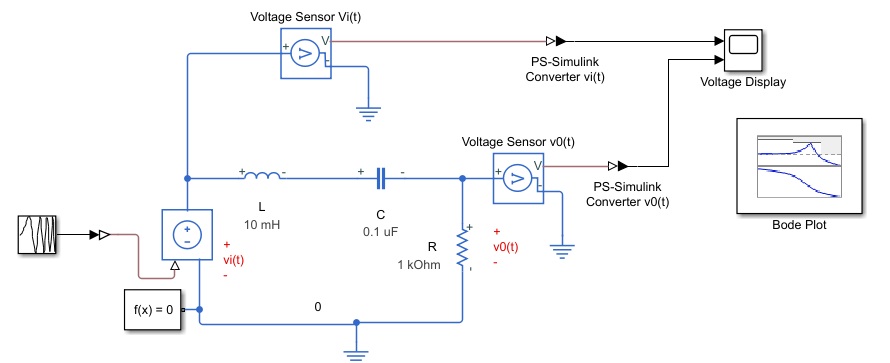

#### Example 4. RLC Circuit

  Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

                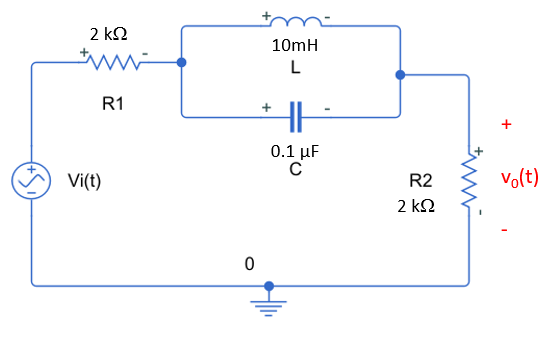               

**Solution:**

Transfer the circuit into $\omega $ domain and assing name to nodes

                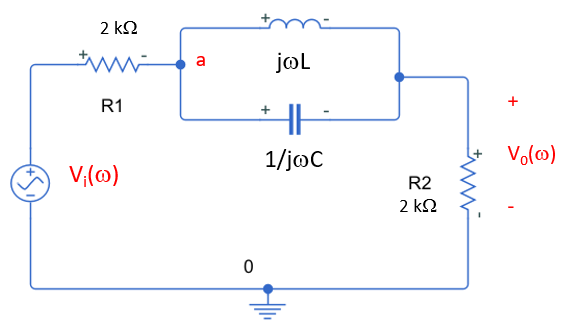

First, find the impedance of $j\omega L ||(1/j\omega C)$

                
$$Z_1=\frac{j\omega L \frac{1}{j\omega C}}{j\omega L+ \frac{1}{j\omega C}}=\frac{j\omega L}{-\omega ^2LC+1}$$


Applying voltage division $V_0(\omega) $ wil be 

                
$$V_0(\omega)= \frac{R_2}{R_1+R_2+\frac{j\omega L}{-\omega ^2LC+1}} V_i(\omega)$$


The transfer function is given

            
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)}= \frac{R_2}{R_1+R_2+\frac{j\omega L}{-\omega ^2LC+1}} $$


Simplify it as 

            
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} =  \frac{R_2(-\omega ^2LC+1)}{R_1+R_2(-\omega ^2LC+1)+ j\omega L} $$


            
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} =  \frac{R_2}{R_1+R_2} \frac {-\omega ^2LC+1}{-\omega ^2LC+1+ \frac{ j\omega L}{R_1+R_2}} $$


            
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} =  \frac{R_2}{R_1+R_2} \frac {-\omega ^2+\frac{1}{LC}}{-\omega ^2+ \frac{ j\omega}{(R_1+R_2)C}+\frac{1}{LC}} $$


syms H(w)
R1 = 2e3;
R2 = 2e3;
C = 0.1e-6;
L = 10e-3;

H(w) = R2/(R1+R2)*(-w^2+1/(L*C))/(-w^2+j*w/((R1+R2)*C)+1/(L*C))


The magnitude response is given by

            
$$|H(\omega)| = \frac{|V_0(\omega)|}{|V_i(\omega)|} =   \frac{R_2}{R_1+R_2} \frac {|-\omega ^2+\frac{1}{LC}|}{\sqrt{ \Big (-\omega ^2+\frac{1}{LC} \Big )^2+\Big ( \frac{ \omega}{(R_1+R_2)C} \Big)^2} $$
     

and the phase response is given by

              
$$\angle {H(\omega)} = -tan^{-1} \Big(  \frac { \frac{\omega}{(R_1+R_2)C}} {\frac{1}{LC} -\omega ^2} \Big )$$


The maagnitude response  can be calculated in logarithmic form as

            
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

figure ()
subplot (2,1,1)
w = logspace(2,6);    % Define w as a vector containing the frequencies from 10 rad/s to 1,000,000 rad/s.

H = R2/(R1+R2)*(-w.^2+1/(L*C))./(-w.^2+j*w./((R1+R2)*C)+1/(L*C));
% semilogx(w, abs(H))
semilogx(w, 20*log10(abs(H)))
grid on; grid minor;
xlabel('\omega'); ylabel('|H(\omega)|');

subplot (2,1,2)
semilogx(w, angle(H)*180/pi)
grid on; grid minor;
xlabel('\omega'); ylabel('\angle{H(\omega)}');

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_4.slx](matlab:open('./Simulink\Example_4.slx'))

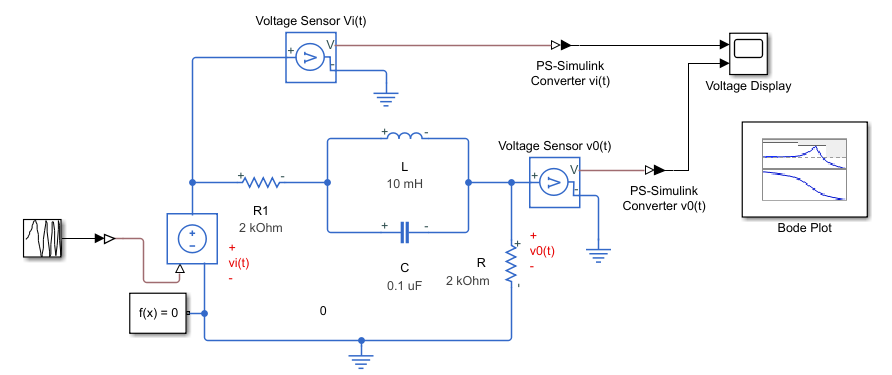

In the simulation, bode plot is shown in the following figure

#### 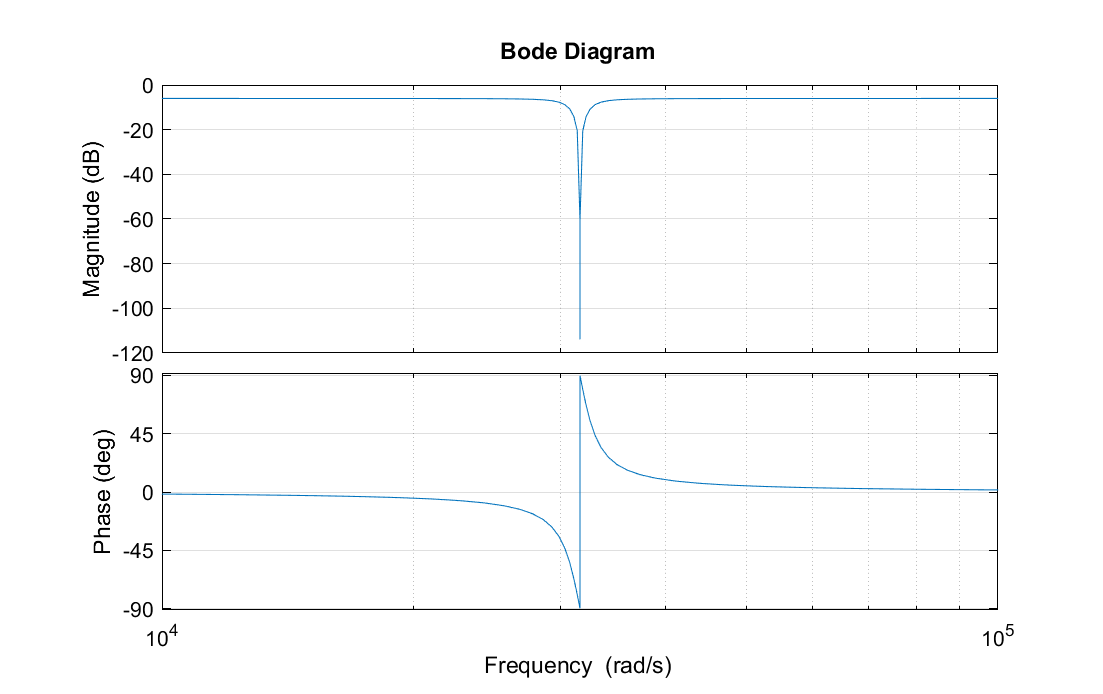

#### Exercise 4. RLC Circuit

  Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

                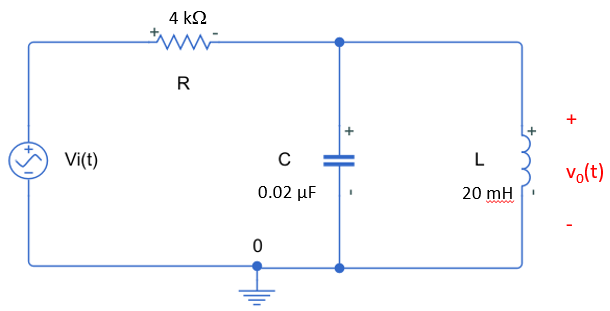               

**Solution Steps:**

Transfer the circuit into $\omega $ domain and assing name to nodes

Apply voltage division to find $V_0(\omega) $ 

Find transfer function is given

Simplify

% syms H(w)
% R = ? ;
% C = ?;
% L = ?;
% 
% H(w) = ?


Find the magnitude response

        
$$|H(\omega)| = \frac{|V_0(\omega)|}{|V_i(\omega)|} = ?$$
     

and the phase response 

      
$$\angle {H(\omega)} = ?$$


The magnitude response  can be calculated in dB form as

        
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

% figure ()
% subplot (2,1,1)
% w = logspace(2,6);    % Define w as a vector containing the frequencies from 10 rad/s to 1,000,000 rad/s.
% 
% H = ?;
% % semilogx(w, abs(H))
% semilogx(w, 20*log10(abs(H)))
% grid on; grid minor;
% xlabel('\omega'); ylabel('|H(\omega)|');
% 
% subplot (2,1,2)
% semilogx(w, angle(H)*180/pi)
% grid on; grid minor;
% xlabel('\omega'); ylabel('\angle{H(\omega)}');

Simulate  this exercise using MATLAB Simulink to chek Bode plot. 

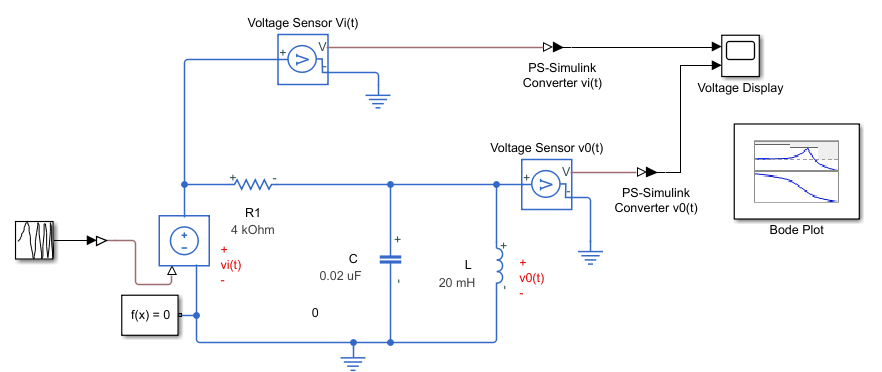

#### Example 5. Op-Amp circuit

Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

               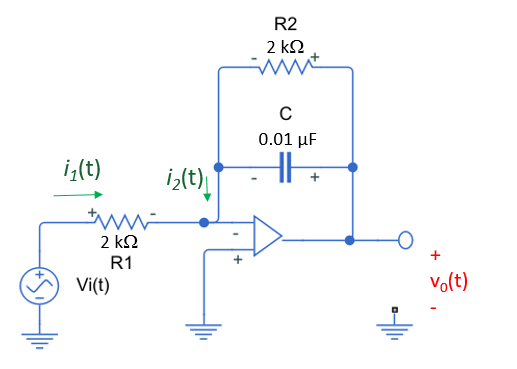

**Solution:**

Transfer the circuit into $\omega $ domain 

            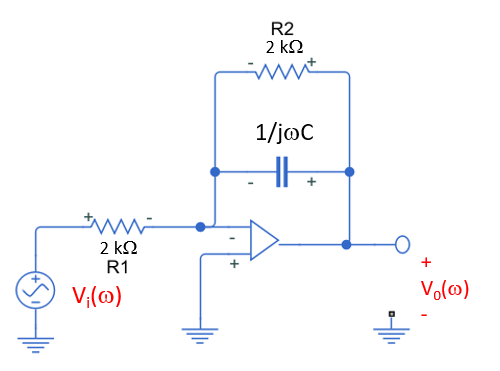

Applying KCl at node to find $V_0(\omega)$

        
$$\frac{V_i(\omega) -0}{R_1} +  \frac{ V_0 (\omega )-0}{R_2} + \frac{ V_0( \omega )-0}{\frac{1}{j\omega C} }= 0$$


Rearange it 

        
$$\Big ( j \omega C+\frac{1}{R_1} \Big)V_0(\omega) = -\frac{1}{R_1} V_i (\omega)$$


The transfer function is given

        
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} =- \frac{ \frac{1}{R_1}} {  j \omega C+\frac{1}{R_2}}  $$


        
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} =- \frac{ \frac{1}{R_1C}} {  j \omega +\frac{1}{R_2C}}  $$


        
$$H(\omega)= \frac{V_0(\omega)}{V_i(\omega)} =-\frac{R_2}{R_1}  \frac{  \frac{1}{R_2C}} {j \omega +\frac{1}{R_2C}}  $$


syms H(w)
R1 = 2e3;
R2 = 2e3;
C=0.01e-6;

H(w)=-(R2/R1)*(1/(R2*C)/(j*w+1/(R2*C)))


The magnitude response is given by

        
$$|H(\omega)| = \frac{|V_0(\omega)|}{|V_i(\omega)|} =\frac{R_2}{R_1}  \frac{  \frac{1}{R_2C}} {\sqrt { \omega^2 +(\frac{1}{R_2C})^2}}  $$
     

and the phase response is given by

          
$$\angle {H(\omega)} = -tan^{-1} \Big( \frac{ \omega } { \frac{1}{R_2C}} \Big ) $$


The maagnitude response  can be claculated in logarithmic form as

        
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

figure()
subplot (2,1,1)
w = logspace(2,6);    % Define w as a vector containing the frequencies from 10 rad/s to 1,000,000 rad/s.

H = -(R2/R1)*(1/(R2*C)./(j*w+1/(R2*C)));
% semilogx(w, abs(H))
semilogx(w, 20*log10(abs(H)))
grid on; grid minor;
xlabel('\omega'); ylabel('|H(\omega)|');

subplot (2,1,2)
semilogx(w, angle(H)*180/pi)
grid on; grid minor;
xlabel('\omega'); ylabel('\angle{H(\omega)}');

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_5.slx](matlab:open('./Simulink\Example_5.slx'))

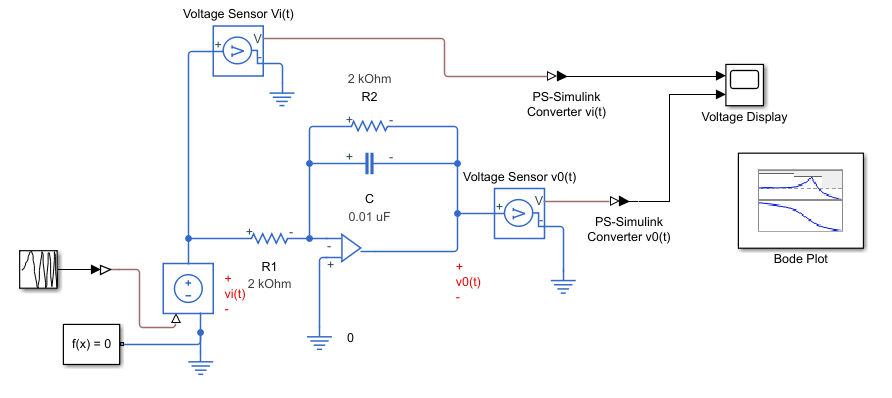

In the simulation, bode plot is shown in the following figure

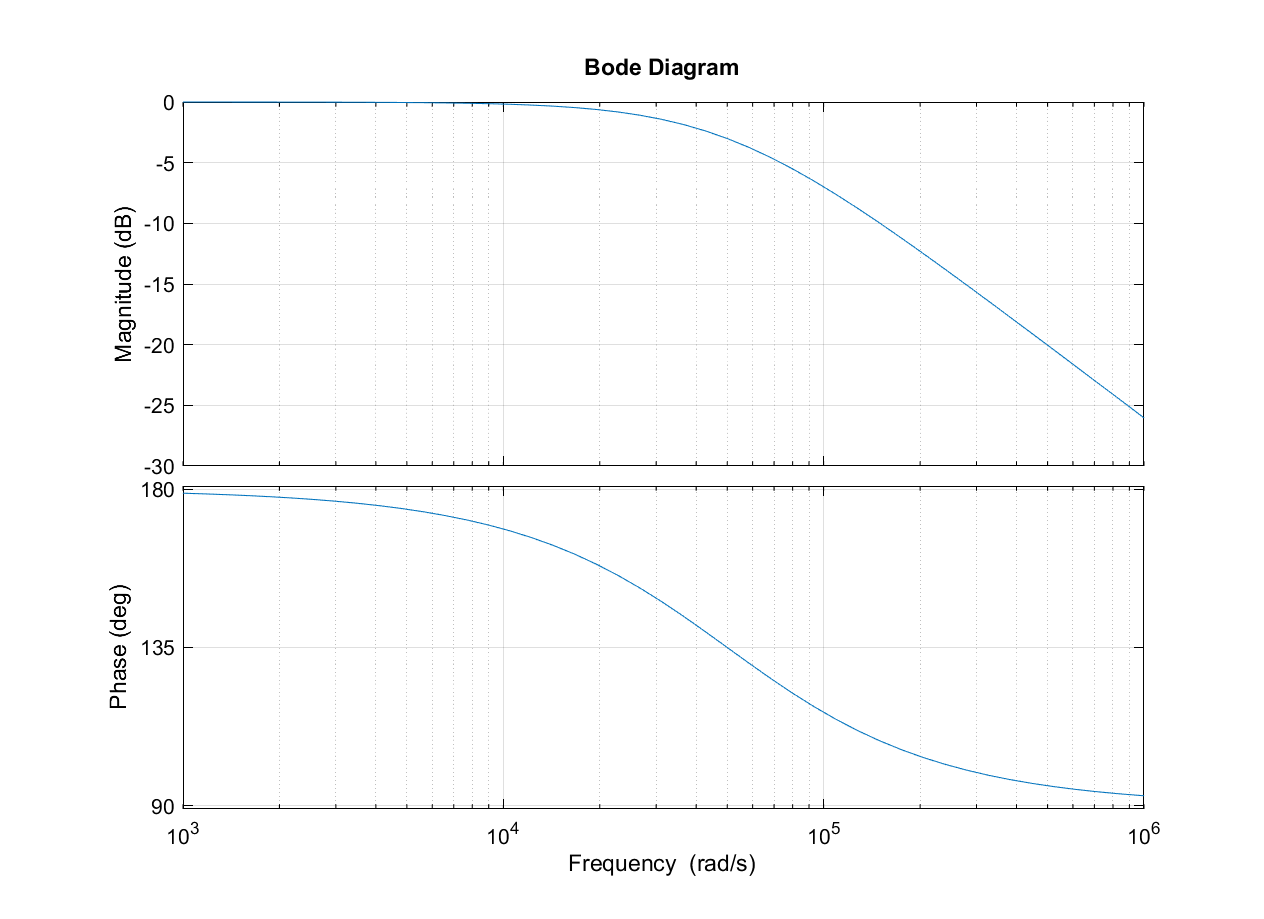

#### Exercise 5. Op-Amp circuit

 Find the transfer function $H(\omega)=\frac{V_0 (\omega)}{V_i (\omega)}$ for the circuit shown and plot the magnitude and phase responses

               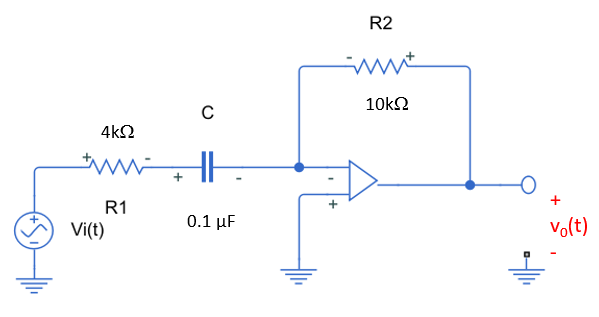

**Solution:**

Transfer the circuit into $\omega $ domain 

Apply  to find $V_0(\omega)$

Rearange it 

Find the  transfer function is given

% syms H(w)
% R1 = ?;
% R2 = ?;
% C=?;
% 
% H(w) = ?


Find the magnitude response is given by

and find the phase response is given by

The maagnitude response  can be calculated in logarithmic form as

        
$$H(\omega)[dB]=20log_{10} |H(\omega)|$$


Plot  magnitude response and  phase response

% subplot (2,1,1)
% w = logspace(2,6);    % Define w as a vector containing the frequencies from 10 rad/s to 1,000,000 rad/s.
% 
% H = ??
% % semilogx(w, abs(H))
% semilogx(w, 20*log10(abs(H)))
% grid on; grid minor;
% xlabel('\omega'); ylabel('|H(\omega)|');
% 
% subplot (2,1,2)
% semilogx(w, angle(H)*180/pi)
% grid on; grid minor;
% xlabel('\omega'); ylabel('\angle{H(\omega)}');

Simulate  this exercise using MATLAB Simulink to chek your values. 

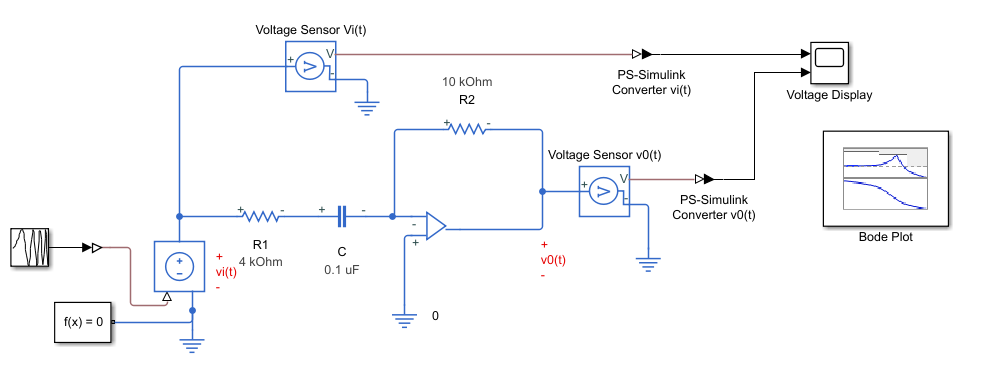

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018